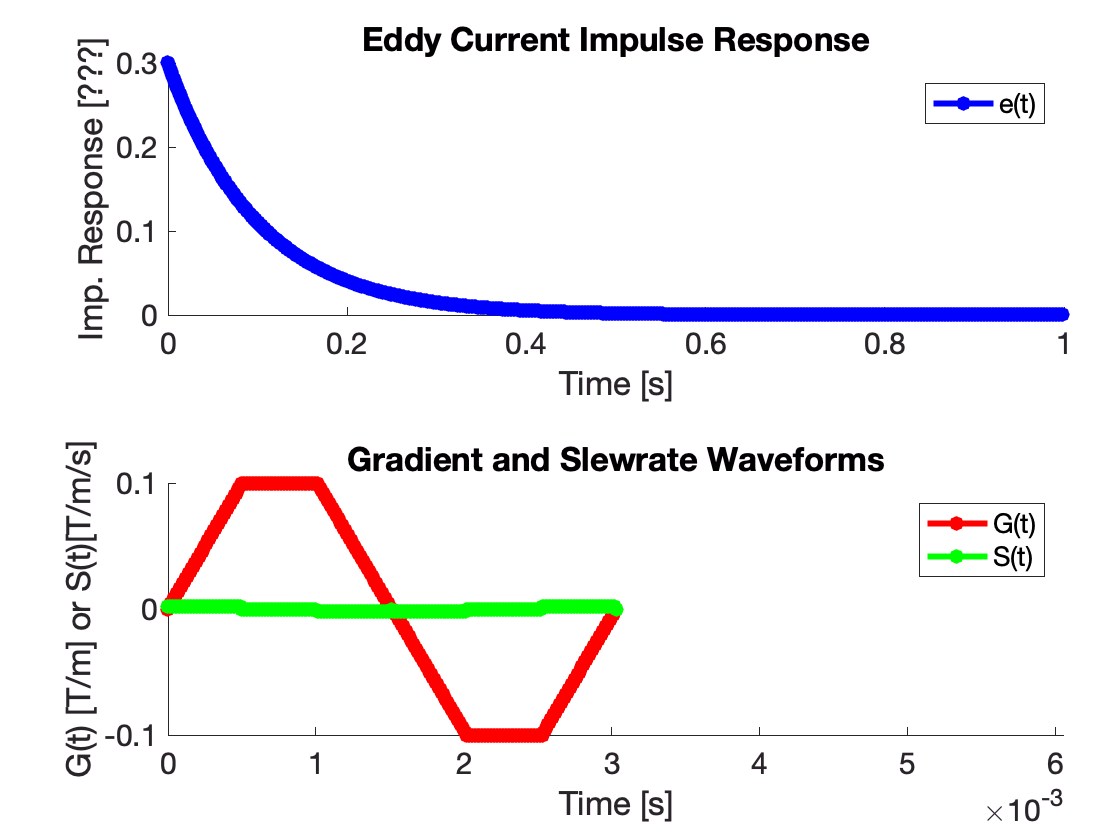

%% This script demonstrates the convolution of a single time-constant eddy 
%  current impulse response function with a trapezoidal gradient waveform.
%
% Define the gradient and slewrate waveform
dt=10e-6;     % Time-step        [s]
G_max=100e-3;  % Gradient maximum [T/m]
S_max=200;     % Slewrate maximum [T/m/s]
dG=S_max*dt;   % Maximum gradient increment per time step

G_rise=0:dG:G_max;
G_flat=G_max*ones(1,50);
G_fall=G_max:-dG:0;

% Monopolar Gradient
G=[G_rise G_flat G_fall];     % Concatenate the gradient events
t=0:dt:dt*(length(G)-1);      % Time vector [ms]

% % Bipolar Gradient
G=[G_rise G_flat G_fall -G_rise -G_flat -G_fall];     % Concatenate the gradient events
t=0:dt:dt*(length(G)-1);      % Time vector [ms]

S=[diff(G) 0];                % Slewrate calculation

%% Define the eddy current response
tau(1)=100.0e-3;           % Eddy current time constant [s]
alpha(1)=0.3;             % Eddy current amplitude
tt=0:dt:10*(max(tau));    % Time vector [ms]

% tau(2)=5.0e-3;           % Eddy current time constant [s]
% alpha(2)=0.3;            % Eddy current amplitude

e=zeros(1,length(tt));
for i=1:length(tau)
  e=e+alpha(i)*exp(-tt/tau(i));
end

%% Define the resultant B0 eddy current field
B0_e=conv(-S,e);               % Zeroth order eddy current
t_e=0:dt:dt*(length(B0_e)-1);  % Time vector [ms]

%% Define the eddy current gradient vector [B0_e + G]
G_e=B0_e+[G zeros(1,length(B0_e)-length(G))];

%% Show the results
set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',15);
f=figure; axis off; hold on;

ax1=axes('position',[0.15 0.625 0.80 0.30]); hold on;
  title('Eddy Current Impulse Response')
  xlabel('Time [s]'); ylabel('Imp. Response [???]');
  plot(tt,e,'b.-'); legend('e(t)'); xlim([0 max([max(t) max(tt)])]);
  
ax1=axes('position',[0.15 0.125 0.80 0.30]); hold on;
  title('Gradient and Slewrate Waveforms')  
  xlabel('Time [s]'); ylabel('G(t) [T/m] or S(t)[T/m/s]');
  plot(t,G,'r.-'); plot(t,S,'g.-'); legend('G(t)','S(t)'); xlim([0 2*max(t)]);

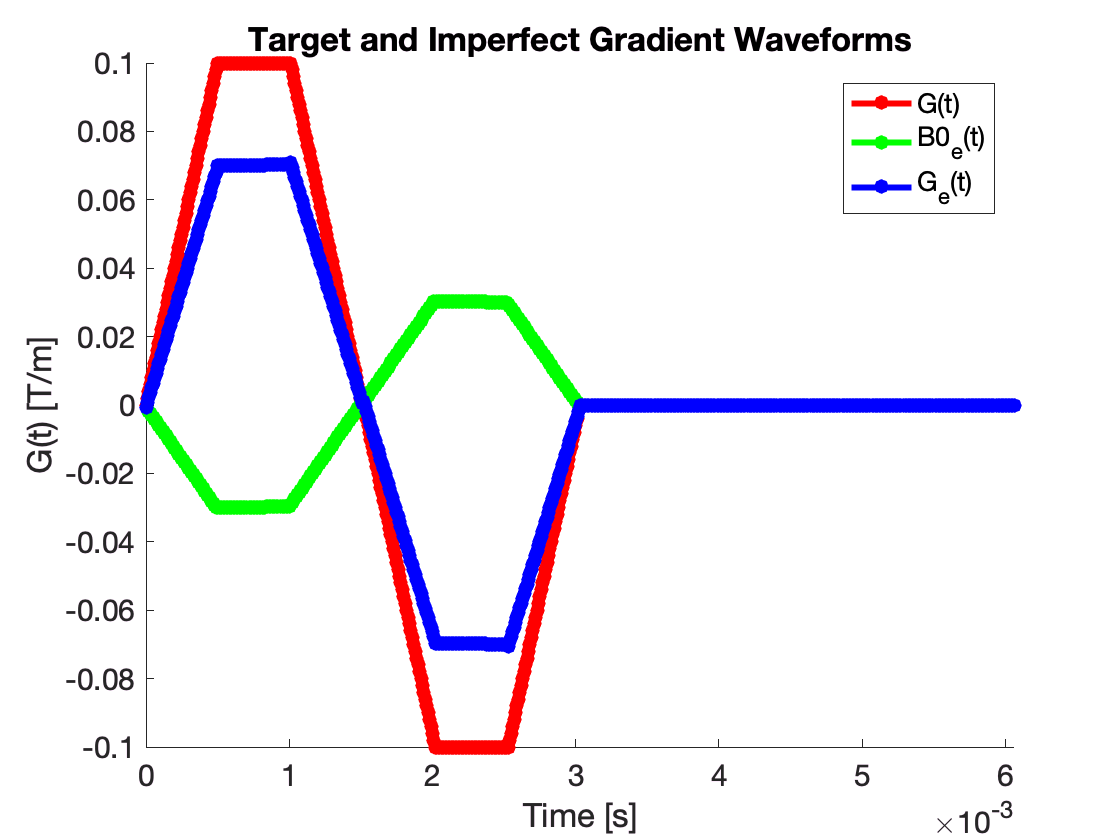


f=figure; hold on;
  title('Target and Imperfect Gradient Waveforms')  
  xlabel('Time [s]'); ylabel('G(t) [T/m]');
  plot(t,G,'r.-'); plot(t_e,B0_e,'g.-'); plot(t_e,G_e,'b.-');
  legend('G(t)','B0_e(t)','G_e(t)'); xlim([0 2*max(t)]);